# Algoritmo Risolve

***Data una generica matrice quadrata di numeri reali A ed un generico vettore b. L'algoritmo Risolve calcola la soluzione di un sistema lineare Ax=b.***

## Sintassi e Descrizione

- `x = risolve(A,b,opt)`  restituisce un vettore di dimensione n soluzione del sistema di equazioni lineari Ax=b. 

## Parametri di input

**A - Matrice dei coefficienti**

Matrice dei coefficienti, può essere una matrice quadrata piena, triangolare superiore o triangolare inferiore. Affinchè la soluzione sia accurata, la matrice A dev'essere ben condizionata. Prima di eseguire l'algoritmo è possibile ricavare l'indice di condizionamento di A tramite [rcond(A)](https://it.mathworks.com/help/matlab/ref/rcond.html).

*Data Types***: **`single | double`

**b - Vettore dei termini noti**

Vettore dei termini noti, ossia un vettore colonna avente lo stesso numero di righe della matrice `A`.

*Data Types*: `single | double`

**opt - Struttura informativa di A**

Struttura contenente almeno uno dei seguenti campi `booleani`:

- `full`: `true` se la matrice `A` è piena, `false` altrimenti;

- `sup`: `true` se la matrice A è triangolare superiore, `false` altrimenti;

- `inf`: `true` se la matrice A è triangolare inferiore, `false` altrimenti.

Uno e un solo campo della struttura può essere `true`.

*Data Types*: `logical`

## Parametri di output

**x :Soluzione del sistema **restituita come un vettore colonna.

## Diagramma di flusso

Supponendo che A sia una matrice e che b sia un input valido, segue il diagramma di flusso di `risolve` che lo descrive ad alto livello [2]. 

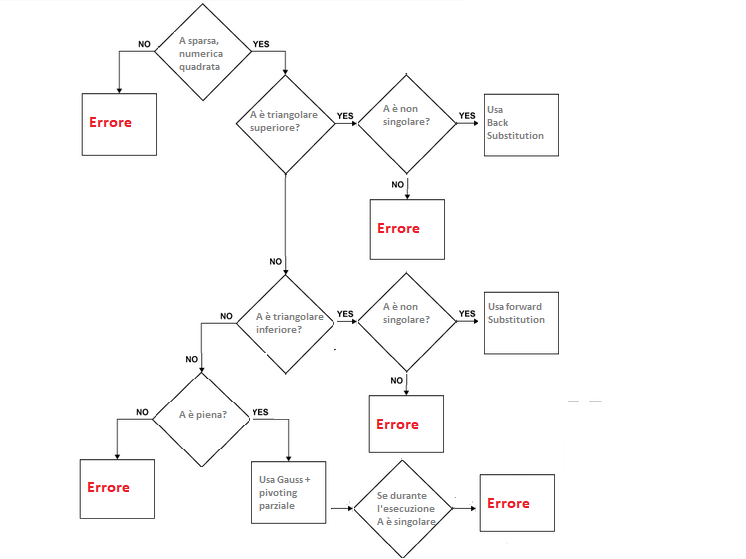

## Esempi di utilizzo

Risolve un semplice sistema di equazioni lineari Ax=b con matrice A piena.

`Command Line Matlab`

A =  rand(3); 
b = rand(3,1); 
opt.full = true;
opt.sup = false;
opt.inf = false;
x = risolve(A,b,opt) 

x =    -0.7728
    1.1407
    0.7745


Risolve un semplice sistema di equazioni lineari Ax=b con matrice A triangolare superiore.

`Command Line Matlab`

A = triu(rand(3)); 
b = rand(3,1); 
opt.full = false;
opt.sup = true;
opt.inf = false;
x = risolve(A,b,opt) 

x =    -3.0274
    0.0038
    2.9736


Risolve un semplice sistema di equazioni lineari Ax=b con matrice A triangolare inferiore.

`Command Line Matlab`

A = tril(rand(3)); 
b = rand(3,1); 
opt.full = false;
opt.sup = false;
opt.inf = true;
x = risolve(A,b,opt) 

x =     0.7049
    0.5062
   -1.1591


## **Esecuzione da interfaccia grafica**

Si può utilizzare la funzione algoritmo risolve attraverso l'interfaccia grafica appositamente implementata. Il comando per utilizzare l'interfaccia è **run MainGui()**`.` 

## Riferimenti

[Docenti.unina.it D'alessio Alessandra](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

[2] Documentazione `Mldivide-flowchart `

## Autori

` Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936`